## Intro

Let's have a look at Extreme Learning Machines with Matlab (to freshen up our skills w/ Matlab!)

The Extreme Learning Machine (ELM) is a learning algorithm that first appeared in [Guang-Bin Huang, Qin-Yu Zhu, Chee-Kheong Siew. "Extreme learning machine: Theory and applications", Neurocomputing (70), pp. 489 - 501, 2006](https://www.ntu.edu.sg/home/egbhuang/pdf/ELM-NC-2006.pdf) for single-hidden layer feedforward neural networks, which randomly chooses hidden nodes and analytically determines the output weights of the neural network. It has been reported to show good generalization performance at extremely fast learning speeds. Here, we'll implement the training algorithm as presented in the above paper, and also try it on one of the referenced datasets, just to get familiar with the concept:

## Implementation

### Dummy dataset

At first, let's generate a dummy dataset, to illustrate the training and prediction process. We will use the same example as in the reference in the beginning, i.e. we will approximate the 'sinC' function:

$y\left(x\right)=\left\lbrace \begin{array}{ll}
\frac{\sin \left(x\right)}{x} & x\not= 0\\
1 & x=0
\end{array}\right.$,

and to make the regression problem 'real', we'll add uniform noise distributed in $\left\lbrack -0\ldotp 2,0\ldotp 2\right\rbrack$, while keeping the testing data, noise-free.

% Initialize the random number generator
rng(0,'twister'); 

% Make dummy dataset (sinC function)
noSamples      = 5e3; % No. data points
x              = linspace(-10, 10, noSamples)';
ySinc          = NaN(size(x));
ySinc(x ~= 0)  = sin(x) ./ x;
ySinc(x == 0)  = 1;

% Add noise to the target
a     = -0.2;
b     = 0.2;
noise = a + (b - a) * rand(size(ySinc));
y     = ySinc + noise; 

% Plot
figure
scatter(x, y, '.', 'displayname', 'sinC w/ noise')

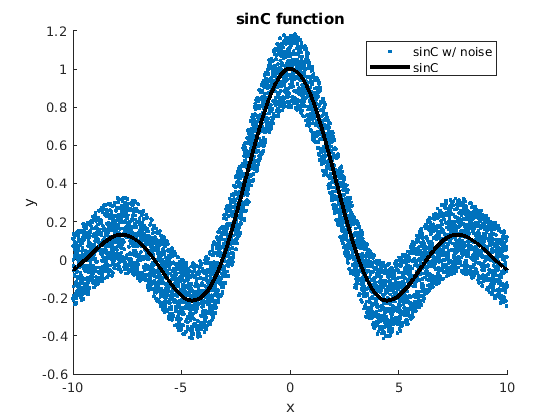

hold on
plot(x, ySinc, 'k', 'linewidth', 3, 'displayname', 'sinC')
xlabel('x')
ylabel('y')
title('sinC function')
legend

We'll use 70% of the data, chosen randomly, as the training set, to which we'll add noise, and the rest 30% noise-free data will be used as the test set:

% Compute no. samples in the training set
nTrain     = floor(0.7 * noSamples);

% Randomly choose the samples in the training set
idxTrain   = randi([1, noSamples], nTrain, 1);
idxTest    = setdiff(1:noSamples, idxTrain);

% Split the dataset into a training and a test set
xTrain     = x(idxTrain);
yTrain     = y(idxTrain);     % train target w/ noise
xTest      = x(idxTest);
yTest      = ySinc(idxTest); % test target, noise-free

### **Training Algorithm**

The training algorithm consists of 3, rather simple steps, as discussed in the following.

At first, let's define some necessary constants:

Ntilde  = 30;                 % No. neurons in the hidden layer
N       = size(yTrain, 1);   % No. samples in the training set
n       = size(xTrain, 2);   % No. inputs per sample
m       = size(yTrain, 2);   % No. outputs per sample

#### **Step 1: Randomly assign input weight vector **${\mathit{\mathbf{w}}}_i ={\left\lbrack w_{\textrm{i1}} ,w_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,w_{\textrm{in}} \right\rbrack }^T \in \Re^n$** and bias **${\mathit{\mathbf{b}}}_i ={\left\lbrack b_{\textrm{i1}} ,b_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,b_{\textrm{im}} \right\rbrack }^T \in \Re^m ,i=1,\cdots ,N$

w = rand([n, Ntilde]);
b = rand([m, Ntilde]);

#### **Step 2: Compute the hidden layer output matrix H**


$$\mathit{\mathbf{H}}\left(w_1 ,\ldotp \ldotp \ldotp ,w_{\tilde{N} } ,b_1 ,\ldotp \ldotp \ldotp ,b_{\tilde{N} } ,x_1 ,\ldotp \ldotp \ldotp ,x_N \right)={\left\lbrack \begin{array}{ccc}
g\left(w_{1\;} x_1 +b_1 \right) & \cdots  & g\left(w_{\tilde{N} } x_1 +b_{\tilde{N} } \right)\\
\vdots  & \ddots  & \vdots \\
g\left(w_{1\;} x_N +b_1 \right) & \cdots  & g\left(w_{\tilde{N} } x_N +b_{\tilde{N} } \right)
\end{array}\right\rbrack }_{N\times \tilde{N} }$$


where:

${\mathit{\mathbf{x}}}_i ={\left\lbrack x_{\textrm{i1}} ,x_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,x_{\textrm{in}} \right\rbrack }^T \in \Re^n ,{\mathit{\mathbf{w}}}_i ={\left\lbrack w_{\textrm{i1}} ,w_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,w_{\textrm{in}} \right\rbrack }^T \in \Re^n$, and g() is the activation function. As proposed in the paper, we'll use the sigmoid function.

H = sigm(xTrain * w + b);

#### **Step 3: Calculate the output weight **$\beta$

$\beta ={\mathit{\mathbf{H}}}^{\dagger } \;\mathit{\mathbf{Y}}$, where ${\mathit{\mathbf{H}}}^{\dagger }$ is the Moore-Penrose generalized inverse of matrix H, given by: ${\mathit{\mathbf{H}}}^{\dagger \;} ={\left({\mathit{\mathbf{H}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{H}}\right)}^{-1} {\mathit{\mathbf{H}}}^{\mathit{\mathbf{T}}\;} \ldotp$

Here, we will use the computational procedure of [Fast Computation of Moore-Penrose Inverse Matrices, Pierre Courrieu](https://arxiv.org/ftp/arxiv/papers/0804/0804.4809.pdf), based on a full rank Cholesky factorization. Implementation can be seen at the end of the notebook, in the pseudo_inv() function.

beta  = pseudoInv(H) * yTrain;

And that's it. We just learned the neural network.

### **Making Predictions**

Making predictions is a simple one-liner. Let's predict on the noise-free test set, and plot the results:

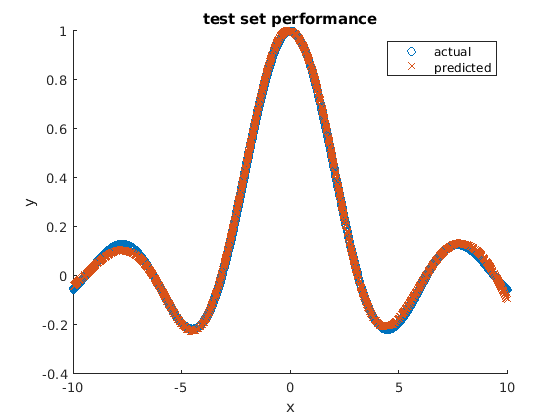

yHat = sigm(xTest * w + b) * beta;

% Plot results
figure
scatter(xTest, yTest, 'displayname', 'actual')
hold on
scatter(xTest, yHat, 'x', 'displayname', 'predicted')
legend
ylabel('y')
xlabel('x')
title('test set performance')

It is clear that the ELM can succesfully predict the sinc function.

### Sensitivity to number of hidden neurons

It will be fairly easy to visualize the performance (root mean square error) of the ELM with a different number of hidden neurons. Let's wrap the above procedure into a few functions for the training and predictions processes (train() and predict() as seen in the end, respectively), and plot performance:

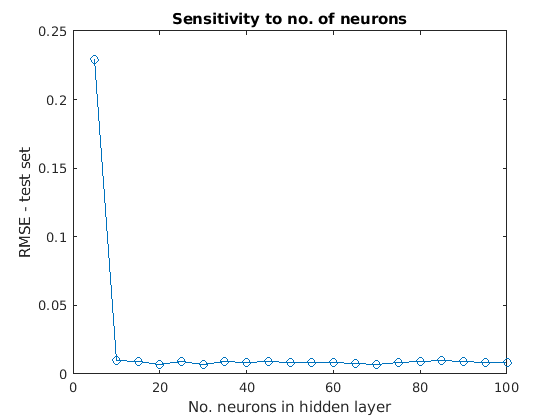

rng(1,'twister'); % Initialize the random number generator

noNeurons = 5:5:100; % Array with different. neuron number
rmse      = NaN(size(noNeurons)); % Array with results

for i = 1:length(noNeurons)
    Ntilde       = noNeurons(i);                   % No. hidden neurons
    [w, b, beta] = train(xTrain, yTrain, Ntilde);  % Training process
    yHat        = predict(xTest, w, b, beta);      % Predictions on the test set
    rmse(i)      = mean(sqrt((yTest - yHat) .^2)); % Root mean square error
end

figure
plot(noNeurons, rmse, '-o')
xlabel('No. neurons in hidden layer')
ylabel('RMSE - test set')
title('Sensitivity to no. of neurons')

Indeed, as the paper reports, the ELM is stable on a wide range of number of hidden neurons, and equally importantly, super-fast!

## Trial on a more realistic dataset

Let's check the performance on a real dataset. We'll use the [Delta elevators](https://www.dcc.fc.up.pt/~ltorgo/Regression/delta_elevators.html) dataset which contains 9517 instances of 6 attributes. It is obtained from the task of controlling the elevators of a F16 aircraft, and its a regression task.

### Quick Preprocessing

Let's prepare the dataset for the ELM. We'll do a simple train/test split with the normalization process described in the initial paper:

clear all

% Read data
dset = readtable('deltaElevators.txt');
dset = table2array(dset); % Convert to table

% Make predictors and target
x    = dset(:, 1:6);
y    = dset(:, 7);

% Normalize predictors to [0, 1]
for col = 1:size(x, 2)
    mmax  = max(x(:, col));
    mmin  = min(x(:, col));
    range = mmax - mmin;
    
    x(:, col) = (x(:, col) - mmin) / range;
end

% Normalize targets to [-1, 1]
for col = 1:size(y, 2)
    mmax  = max(y(:, col));
    mmin  = min(y(:, col));
    range = mmax - mmin;
    y(:, col) = 2 * (y(:, col) - mmin) / range - 1;
end

% Splits a dataset into equally sized train/test sets
    
% Compute no. samples in the training set
noSamples  = size(x, 1);
nTrain     = floor(0.5 * noSamples);
    
% Randomly choose the samples in the training set
idxTrain   = randi([1, noSamples], nTrain, 1);
idxTest    = setdiff(1:noSamples, idxTrain);
    
% Split the dataset into a training and a test set
xTrain     = x(idxTrain, :);
yTrain     = y(idxTrain, :);
xTest      = x(idxTest, :);
yTest      = y(idxTest, :);

### Training and test-set performance

Let's train the network and get the performance on the test set:

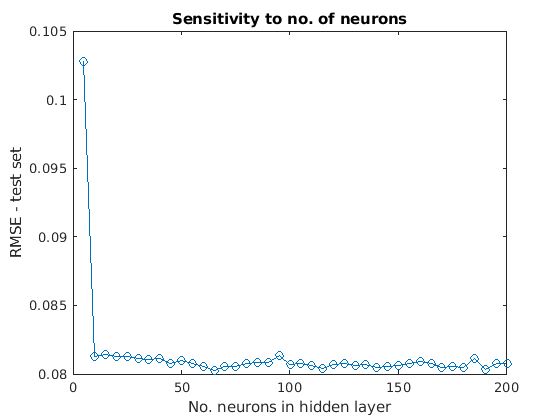

rng(0,'twister'); % Initialize the random number generator

noNeurons = 5:5:200;                              % Array with different. neuron numbers
noTargets = size(yTrain, 2);                      % No. targets for the NN
rmse      = NaN(length(noNeurons), noTargets);    % Arrays with results

for i = 1:length(noNeurons)
    Ntilde       = noNeurons(i);                   % No. hidden neurons
    [w, b, beta] = train(xTrain, yTrain, Ntilde);  % Training process
    yHat         = predict(xTest, w, b, beta);     % Predictions on the test set
    rmse(i, :)   = mean(sqrt((yTest - yHat) .^2)); % RMSE
end

% Plot results
figure
plot(noNeurons, rmse, '-o')
xlabel('No. neurons in hidden layer')
ylabel('RMSE - test set')
title('Sensitivity to no. of neurons')

Once again, the RMSE decreases, flattering to about 0.080 after 6 neurons. In the original paper, the authors reported an RMSE of 0.066 on their test set with 125 hidden neurons. The most remarkable attribute is the training speed (which is on average constant here - probably due to the small number of neurons). Note that most of the training process is spent to compute the Moore-Penrose pseudoinverse matrix.

## Function definitions

In the following, we declare all the functions mentioned in the above sections.

### Sigmoid activation function

function S = sigm(x)
    % Sigmoid activation function of x
    
    S = 1./ (1 + exp(-x));
end

### Moore - Penrose inverse

function Y = pseudoInv(G)
    % Return the Moore-Penrose inverse of the matrix G
    % Transpose if m < n
     
    [m, n]    = size(G); 
    transpose = false;
    
    if m < n
         transpose = true;
         A = G * G';
         n = m;
    else
        A = G' * G;
    end
    
    % Full rank Cholesky factorization of A
    dA  = diag(A); 
    tol =  min(dA(dA > 0)) * 1e-9;
    L   = zeros(size(A));
    r   = 0;
    
    for k=1:n
         r         = r + 1;
         L(k:n, r) = A(k:n, k) - L(k:n, 1:(r - 1)) * L(k, 1:(r - 1))';
         
         % Note: for r = 1, the substracted vector is zero
         if L(k,r) > tol
            L(k,r) = sqrt(L(k, r));
            if k<n
               L((k + 1):n, r) = L((k + 1):n, r) / L(k, r);
            end
         else
            r = r - 1;
         end
    end
    L = L(:, 1:r);
    
     % Computation of the generalized inverse of G
    M = inv(L' * L);
    if transpose
        Y = G' * L * M * M * L';
    else
        Y = L * M * M * L' * G';
    end
end

### Training process

function [w, b, beta] = train(X, y, noNeurons)
    % Training process for an ELM
    
    n = size(X, 2);   % No. inputs per sample
    m = size(y, 2);   % No. outputs per sample
    
    % Step 1
    w    = rand([n, noNeurons]);
    b    = rand([m, noNeurons]);
    beta = NaN([noNeurons, m]);

    for i = 1:m
        % Step 2
        H = sigm(X * w + b(i, :));
    
        % Step 3
        beta(:, i) = pseudoInv(H) * y(:, i);
    end
end

### Prediction

function yHat = predict(X, w, b, beta)
    % Prediction on matrix X, with parameters w, b, beta
    
    m    = size(b, 1); % No. outputs per sample
    N    = size(X, 1); % No. observations to predict for
    yHat = NaN(N, m);  % Empty matrix to hold results
    
    % Predict each target
    for i = 1:m
        yHat(:, i) = sigm(X * w + b(i, :)) * beta(:, i);
    end
end